Testing and plotting SIFT features

I = im2gray(imread("247007.jpg"));
I = imresize(I, [256 256]);
sift = detectSIFTFeatures(I,ContrastThreshold=0.0133,EdgeThreshold = 10);
figure, imshow(I), hold on;
% plot(sift.selectStrongest(100))
sift = sift.selectStrongest(100)

sift =   5×1 SIFTPoints array with properties:

          Scale: [5×1 single]
    Orientation: [5×1 single]
         Octave: [5×1 int32]
          Layer: [5×1 int32]
       Location: [5×2 single]
         Metric: [5×1 single]
          Count: 5


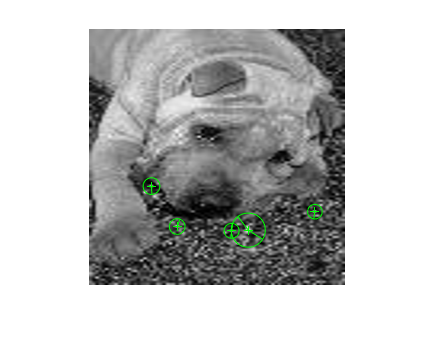

[features, valid_points] = extractFeatures(I, sift);
plot(valid_points,'showOrientation',true);

%CIFAR100
% rootFolder = 'cifar-100-matlab\CIFAR-100\TEST';
% categories = {'cup','dinosaur','forest','hamster'};

%COREL80
rootFolder = 'CorelDB';
categories = {'bld_castle','sc_sunset','wl_buttrfly','wl_deer'};

imds = imageDatastore(fullfile(rootFolder, categories), 'LabelSource', 'foldernames');
imds.ReadFcn = @readFunctionTrain;

% Change the number 50 to as many training images as you would like to use
% how does increasing the number of images change the 
% accuracy of the classifier?
imagesPerClass = 100

imagesPerClass = 100

[trainingSet, ~] = splitEachLabel(imds, imagesPerClass, 'randomize'); 

featureSet = [];
ref = [];
numImages = numel(trainingSet.Files);

% preprocess the images in the dataset and collect:
% - their SIFT features into the featureSet matrix
% - their original image ID into the ref vector
for i = 1 : numImages
    I = im2gray(readimage(trainingSet,i));
    I = imresize(I, [256 256]); % can try without this
    sift = detectSIFTFeatures(I);
    sift = sift.selectStrongest(100);
    [features, sift_points] = extractFeatures(I, sift);
    featureSet = [featureSet features.'];
    ref = [ref repmat([i], 1, size(features,1))];
end


% construct LSH hash tables for featureSet

% Tune hyperparameters
Q = 125;   % # of queries
K = 32;   % # of nearest neighbors to search for each query
L = 5;    % # of tables
M = 10;   % # of dimensions at projection space
W = 1000; % bucket width
T = 10;   % # of additional probing bins

% Construct index tables
lshStruct = lshConstruct(featureSet, L, M, W);

Creating table 1/5
	Projecting data...
	2626 buckets
	min / max size: 1 / 1682
	mean / median: 1.820030e+01 / 2
Creating table 2/5
	Projecting data...
	2645 buckets
	min / max size: 1 / 2170
	mean / median: 1.806957e+01 / 2
Creating table 3/5
	Projecting data...
	2929 buckets
	min / max size: 1 / 1675
	mean / median: 1.631751e+01 / 2
Creating table 4/5
	Projecting data...
	2928 buckets
	min / max size: 1 / 1578
	mean / median: 1.632309e+01 / 2
Creating table 5/5
	Projecting data...
	2930 buckets
	min / max size: 1 / 1526
	mean / median: 1.631195e+01 / 2
Total time: 0.119694


% query an input image
% [idsSIMPLE, cand_sizeSIMPLE, binsFound_ratiosSIMPLE] = lshSearch(Qfeatures, X, lshStruct, K);
[idsMULTIPROBE, cand_sizeMULTIPROBE, binsFound_ratiosMULTIPROBE] = lshSearch(featureSet(:, 1:Q), featureSet, lshStruct, K, T);

Retrieving candidates from table 1
	-----> 0.161550 seconds
Retrieving candidates from table 2
	-----> 0.143276 seconds
Retrieving candidates from table 3
	-----> 0.144705 seconds
Retrieving candidates from table 4
	-----> 0.137688 seconds
Retrieving candidates from table 5
	-----> 0.137424 seconds
Removing duplicate candidates...
	-----> 0.002968 seconds
Performing knn search...
	-----> 0.007243 seconds
Calculating candidate sizes...
	-----> 0.028823 seconds


% convert the feature IDs into their original image IDs
oriImages = zeros(size(idsMULTIPROBE));
for i = 1 : size(idsMULTIPROBE, 1)
    for j = 1 : size(idsMULTIPROBE, 2)
        if idsMULTIPROBE(i, j)>0
          oriImages(i,j) = ref(:,idsMULTIPROBE(i, j));
        end
    end
end

% aggregate and weight the image features by their ranks 
uniqImageIds = unique(oriImages);
N = numel(uniqImageIds);
weights = zeros(N,1);

fib = zeros(1, K), fib(K-1) = 1;

fib =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


for i = K-2:-1:1
   fib(i) = fib(i+1)+fib(i+2);
end

for k = 1 : N
%   count(k) = sum(sum(oriImages==uniqImageIds(k)));
%   exp(N-k+1)
%   count(k) = exp(N - k + 1) * sum(sum(oriImages == uniqImageIds(k)));
%   count(k) = sum((K + (0 : K - 1) * -1) * (oriImages == uniqImageIds(k)));
  weights(k) = sum((fib) * (oriImages == uniqImageIds(k)));
end

ranks = sortrows([weights uniqImageIds], 1, 'descend');

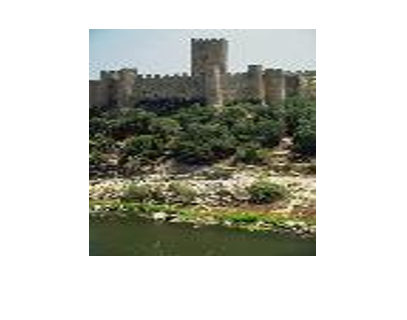

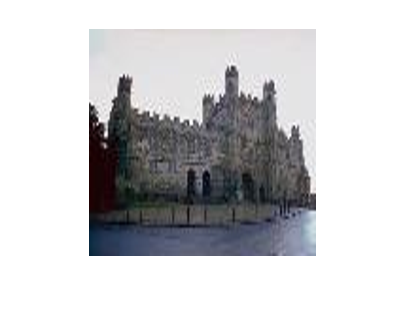

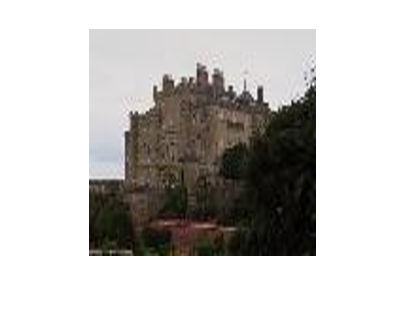

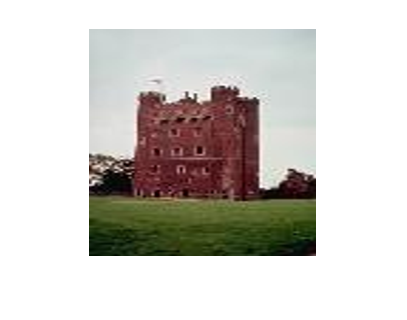

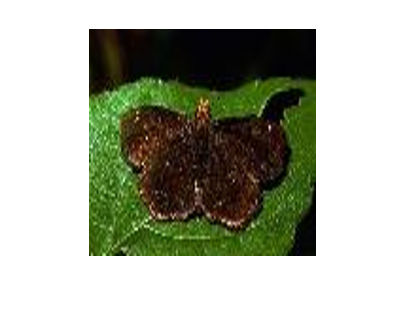

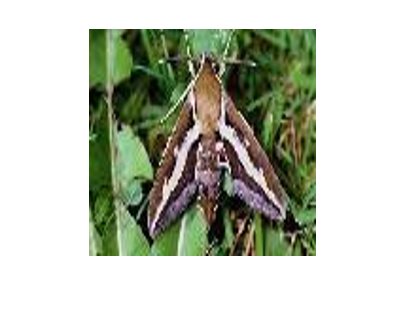

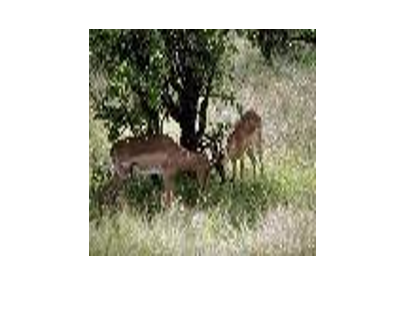

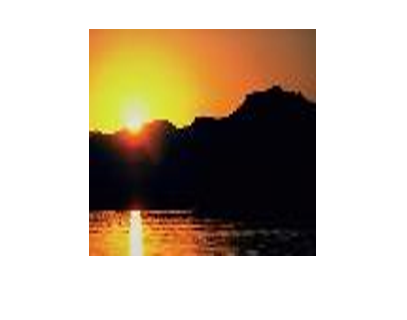

% display all the matching images
for pic = 1:min(20,length(ranks))
    if ranks(pic,2)>0
        I = readimage(trainingSet, ranks(pic, 2));
        figure, imshow(I);
    end
end